# Assignment 1.1: Teaching a Cylrindrical Mechanical Manipualtor (RRP)

Objective:

 - to create and to simulate a Cylindrical Mechanical Manipulator using the Robotics Toolbox for MATLAB by Peter Corke

disp("SCARA Second Variant")

SCARA Second Variant


syms a1 a2 a3 a4

## Step 1: Define the Link Lengths

a1 = 5;
a2 = 5;
a3 = 5;
a4 = 5;

## Step 2: Using the Prismatic and Revolute class to create the HTM

H_01 = Prismatic('alpha', pi/2, 'offset', -a1) 

 
H_01 = 
Prismatic(std): theta=0, d=q, a=0, alpha=1.5708, offset=-5


H_12 = Prismatic('theta', pi/2 , 'alpha', pi/2, 'offset', a2)

 
H_12 = 
Prismatic(std): theta=1.5708, d=q, a=0, alpha=1.5708, offset=5


H_23 = Prismatic('theta', pi/2 , 'alpha', 3*pi/2, 'offset', a3)

 
H_23 = 
Prismatic(std): theta=1.5708, d=q, a=0, alpha=4.71239, offset=5


H_34 = Prismatic('offset', a4)

 
H_34 = 
Prismatic(std): theta=0, d=q, a=0, alpha=0, offset=5



% define the following limits

H_01.qlim = [0, 5];
H_12.qlim = [0, 5];
H_23.qlim = [0, 5];
H_34.qlim = [0, 5];

## Step 3: Create the Manipulator via Serial Link Class

spherical_manip = SerialLink([H_01, H_12, H_23, H_34], 'name', 'SCARA Second Variant')

 
spherical_manip = 
 
SCARA Second Variant:: 4 axis, PPPP, stdDH, slowRNE              
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|          0|         q1|          0|     1.5708|         -5|
|  2|     1.5708|         q2|          0|     1.5708|          5|
|  3|     1.5708|         q3|          0|    4.71239|          5|
|  4|          0|         q4|          0|          0|          5|
+---+-----------+-----------+-----------+-----------+-----------+
 


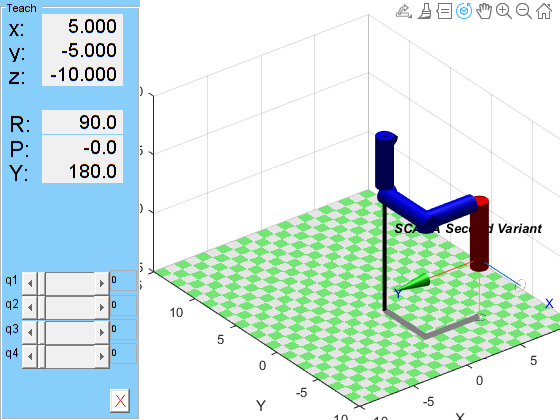


joint_setpoint = [0,0,0,0];
workspace = [-10, 10, -10, 15, -15, 0];
spherical_manip.plot(joint_setpoint, 'workspace', workspace);
spherical_manip.teach();